# Plot Estimated Channel Magnitude Response for TDL-C Channel Model

Define a channel configuration structure using an [nrTDLChannel](docid:5g_ref#mw_sysobj_nrTDLChannel) System object. Use delay profileTDL-C from TR 38.901 Section 7.7.2. 

SR = 7.68e6;
tdl = nrTDLChannel;
tdl.DelayProfile = 'TDL-C';
tdl.DelaySpread = 100e-9;
% tdl.MaximumDopplerShift = 300;
tdl.MaximumDopplerShift = 300;
tdl.SampleRate = SR;
tdl.NumTransmitAntennas = 1;
tdl.NumReceiveAntennas = 1

tdl =   nrTDLChannel with properties:

                 DelayProfile: 'TDL-C'
                  DelaySpread: 1.0000e-07
          MaximumDopplerShift: 300
                   SampleRate: 7680000
              MIMOCorrelation: 'Low'
                 Polarization: 'Co-Polar'
        TransmissionDirection: 'Downlink'
          NumTransmitAntennas: 1
           NumReceiveAntennas: 1
           NormalizePathGains: true
                  InitialTime: 0
                 NumSinusoids: 48
                 RandomStream: 'mt19937ar with seed'
                         Seed: 73
      NormalizeChannelOutputs: true
             ChannelFiltering: true
    TransmitAndReceiveSwapped: false


% tdl = nrTDLChannel('DelayProfile', 'TDL-C', 'NumTransmitAntennas', 1, 'NumReceiveAntennas', 1, 'SampleRate', 7.68e6);

Create a random waveform with a duration of 1 subframe.

T = SR*1e-3;
tdlInfo = info(tdl);
Nt = tdlInfo.NumTransmitAntennas;
in = complex(randn(T,Nt),randn(T,Nt));

 Transmit the input waveform through the channel. Obtain the path filters used in channel filtering.

[~,pathGains] = tdl(in);
pathFilters = getPathFilters(tdl);

Perform perfect channel estimation using the specified number of blocks, subcarrier spacing, and slot number.

NRB = 25;
SCS = 15;
nSlot = 1;

hest = nrPerfectChannelEstimate(pathGains,pathFilters,NRB,SCS,nSlot);
size(hest)

ans =    300    14


Plot the estimated channel magnitude response for the first receive antenna.

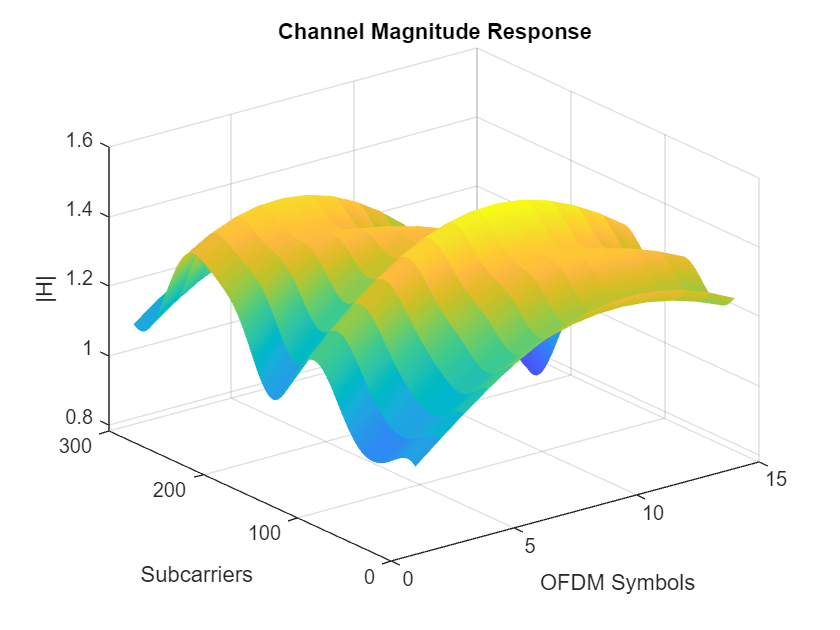

figure;
surf(abs(hest(:,:,1)));
shading('flat');
xlabel('OFDM Symbols');
ylabel('Subcarriers');
zlabel('|H|');
title('Channel Magnitude Response');

Repeat the channel estimate for extended cyclic prefix.

hest = nrPerfectChannelEstimate(pathGains,pathFilters,NRB,SCS, nSlot,'extended');
size(hest)

ans =    300    12


Plot the updated results. 

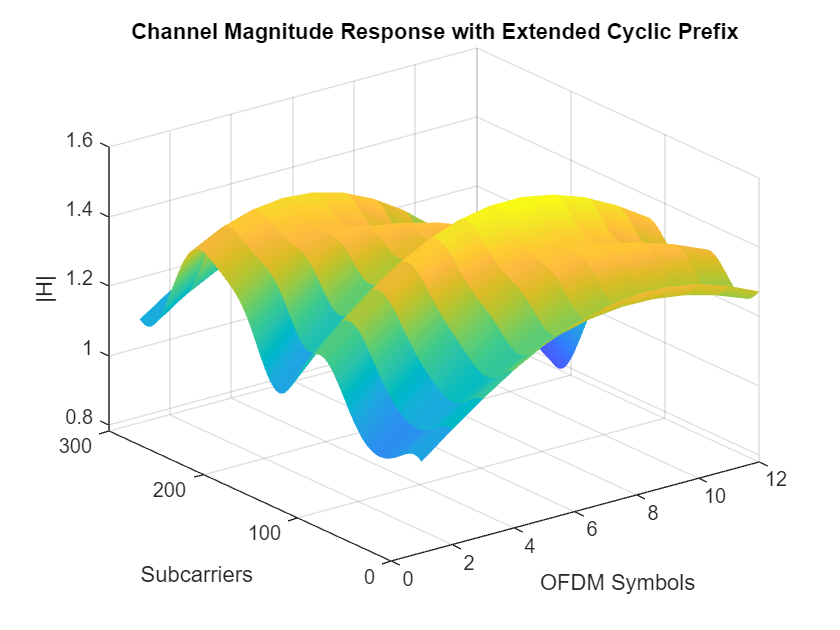

figure;
surf(abs(hest(:,:,1)));
shading('flat');
xlabel('OFDM Symbols');
ylabel('Subcarriers');
zlabel('|H|');
title('Channel Magnitude Response with Extended Cyclic Prefix');

*Copyright 2018 The MathWorks, Inc.*